elbow_figure = figure;
title("Rotation Test")
grid on
hold on
axis([-5 5 -5 5 -5 5])
view([45 25])

T1 = [0 -1 0 3; 0 0 -1 0; 1 0 0 0; 0 0 0 1]

T1 =      0    -1     0     3
     0     0    -1     0
     1     0     0     0
     0     0     0     1


T2 = [1 0 0 0; 0 0 1 2; 0 -1 0 0; 0 0 0 1]

T2 =      1     0     0     0
     0     0     1     2
     0    -1     0     0
     0     0     0     1



transforms = {
    eye(4),
    T1,
    T2
};
lines = draw_axes_for_transforms(transforms, 1)

lines =   141.0002  142.0001  143.0001  144.0001  145.0001  146.0001  147.0001  148.0001  149.0001


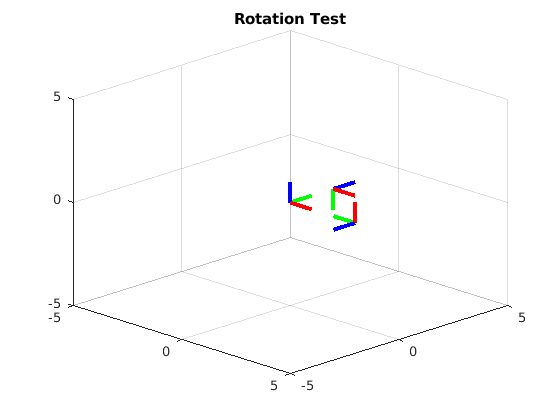


hold off


R = [0 -1 0; 0 0 -1; 1 0 0]

R =      0    -1     0
     0     0    -1
     1     0     0


transpose(R) * [3;0;0]

ans =      0
    -3
     0


[0 0 1 0; -1 0 0 3; 0 -1 0 0; 0 0 0 1;] * [1 0 0 0; 0 0 1 2; 0 -1 0 0; 0 0 0 1]

ans =      0    -1     0     0
    -1     0     0     3
     0     0    -1    -2
     0     0     0     1


cosd(-90)

ans = 0

sind(-90)

ans = -1


T_sa = [0 -1 0 3; 0 0 -1 0; 1 0 0 0; 0 0 0 1;]

T_sa =      0    -1     0     3
     0     0    -1     0
     1     0     0     0
     0     0     0     1


T_sb = [1 0 0 0; 0 0 1 2; 0 -1 0 0; 0 0 0 1;]

T_sb =      1     0     0     0
     0     0     1     2
     0    -1     0     0
     0     0     0     1


T_sa * T_sb

ans =      0     0    -1     1
     0     1     0     0
     1     0     0     0
     0     0     0     1


T_sb * T_sa

ans =      0    -1     0     3
     1     0     0     2
     0     0     1     0
     0     0     0     1



T_sb * [1; 2; 3; 1;]
inv(T_sb)*[1;2;3;1]

inv(T_sa)

[0 0 3; 0 0 0; -3 0 0;]*[0 0 1; -1 0 0; 0 -1 0;]

[0 0 1 0 0 0; -1 0 0 0 0 0; 0 -1 0 0 0 0; 0 -3 0 0 0 1; 0 0 0 -1 0 0; 0 0 -3 0 -1 0;]*[3;2;1;-1;-2;-3;]

ans =      1
     5
    -2
     1


ans =      1
    -3
     0
     1


ans =      0     0     1     0
    -1     0     0     3
     0    -1     0     0
     0     0     0     1


ans =      0    -3     0
     0     0     0
     0     0    -3


ans =      1
    -3
    -2
    -9
     1
    -1


function lines = draw_axes_for_transforms(transforms, line_size)
    lines = [];
    for index = 1:length(transforms)
        [x_line, y_line, z_line] = draw_coordinate_axis(transforms{index}, line_size, 'red', 'green', 'blue');
        lines(end+1) = x_line;
        lines(end+1) = y_line;
        lines(end+1) = z_line;
    end
end

function [x_line, y_line, z_line] = draw_coordinate_axis(transform, length, x_color, y_color, z_color)    
    origin = transform * [0; 0; 0; 1;];
    x = transform * [length; 0;         0;      1; ];
    y = transform * [0;      length;    0;      1; ];
    z = transform * [0;      0;         length; 1; ];
    x_line = line('XData', [origin(1) x(1)], 'YData', [origin(2) x(2)], 'ZData', [origin(3) x(3)], 'Color', x_color, 'LineWidth', 3);
    y_line = line('XData', [origin(1) y(1)], 'YData', [origin(2) y(2)], 'ZData', [origin(3) y(3)], 'Color', y_color, 'LineWidth', 3);
    z_line = line('XData', [origin(1) z(1)], 'YData', [origin(2) z(2)], 'ZData', [origin(3) z(3)], 'Color', z_color, 'LineWidth', 3);
end